## Part 1: Swing-up 

load('swinging_dick.mat');

xhat_EKF = xhat_EKF.data;
xhat_KF = xhat_KF.data;
xhat_luenberger = xhat_luenberger.data;
xtrue = xtrue.data;

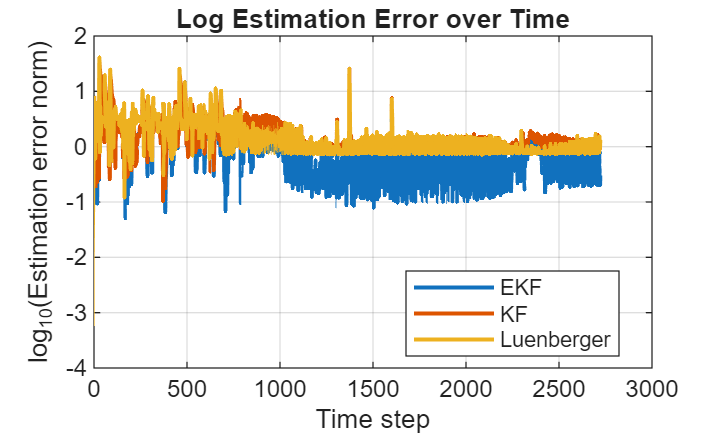

% Calculate the estimation errors for each filter
error_EKF = xtrue - xhat_EKF;
error_KF = xtrue - xhat_KF;
error_luenberger = xtrue - xhat_luenberger;
% plot log estimation error over time
% Compute norm of estimation error at each time step (Euclidean norm)
errNorm_EKF = sqrt(sum(error_EKF.^2,2));
errNorm_KF = sqrt(sum(error_KF.^2,2));
errNorm_luenberger = sqrt(sum(error_luenberger.^2,2));

% Time vector (assume columns correspond to time steps)
T = size(xtrue,1);
t = 1:T;

% Plot log (base 10) of the error norms
figure;
plot(t, log10(errNorm_EKF),'LineWidth',1.5); hold on;
plot(t, log10(errNorm_KF),'LineWidth',1.5);
plot(t, log10(errNorm_luenberger),'LineWidth',1.5);
hold off;
grid on;
xlabel('Time step [0.01 s]');
ylabel('log_{10}(Estimation error norm)');
legend('EKF','KF','Luenberger','Location','best');
title('Log Estimation Error over Time');

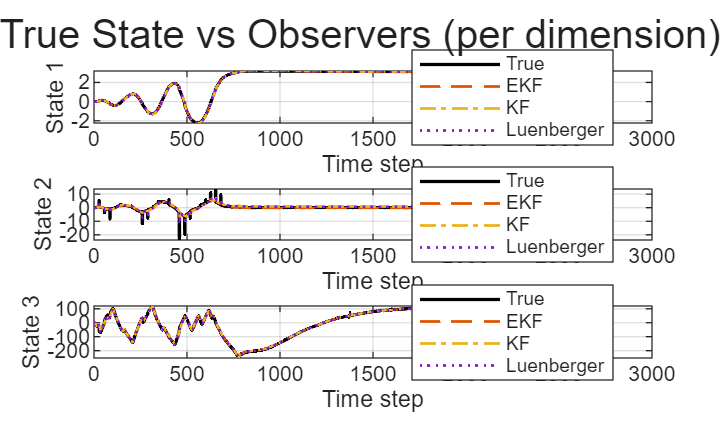

% plot each one
% Create 3 subplots, one for each state dimension, comparing true vs observers
nDims = size(xtrue,2);
figure;
for i = 1:3
    subplot(3,1,i);
    plot(t, xtrue(:,i), 'k-', 'LineWidth', 1.25); hold on;
    plot(t, xhat_EKF(:,i), '--', 'LineWidth', 1);
    plot(t, xhat_KF(:,i), '-.', 'LineWidth', 1);
    plot(t, xhat_luenberger(:,i), ':', 'LineWidth', 1);
    hold off;
    grid on;
    xlabel('Time step [0.01 s]');
    ylabel(sprintf('State %d', i));
    legend('True','EKF','KF','Luenberger','Location','best');
end
sgtitle('True State vs Observers (per dimension)');

## Part 2: Swing-up with disturbances

% extremely swinging dick
load('extremely_swinging_dick.mat');

xhat_EKF = xhat_EKF.data;
xhat_KF = xhat_KF.data;
xhat_luenberger = xhat_luenberger.data;
xtrue = xtrue.data;

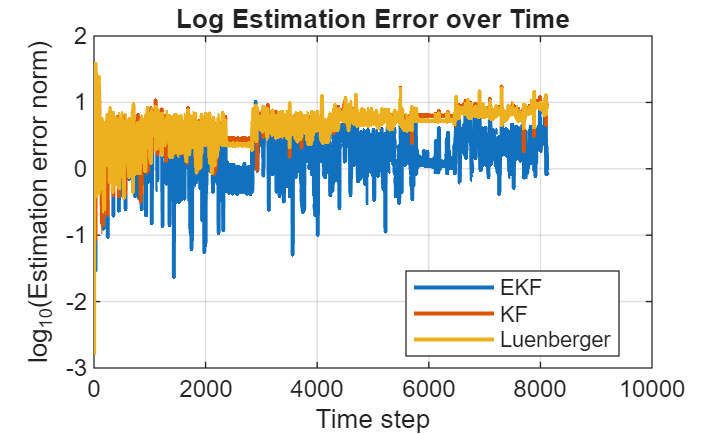

% Calculate the estimation errors for each filter
error_EKF = xtrue - xhat_EKF;
error_KF = xtrue - xhat_KF;
error_luenberger = xtrue - xhat_luenberger;
% plot log estimation error over time
% Compute norm of estimation error at each time step (Euclidean norm)
errNorm_EKF = sqrt(sum(error_EKF.^2,2));
errNorm_KF = sqrt(sum(error_KF.^2,2));
errNorm_luenberger = sqrt(sum(error_luenberger.^2,2));

% Time vector (assume columns correspond to time steps)
T = size(xtrue,1);
t = 1:T;

% Plot log (base 10) of the error norms
figure;
plot(t, log10(errNorm_EKF),'LineWidth',1.5); hold on;
plot(t, log10(errNorm_KF),'LineWidth',1.5);
plot(t, log10(errNorm_luenberger),'LineWidth',1.5);
hold off;
grid on;
xlabel('Time step [0.01 s]');
ylabel('log_{10}(Estimation error norm)');
legend('EKF','KF','Luenberger','Location','best');
title('Log Estimation Error over Time');

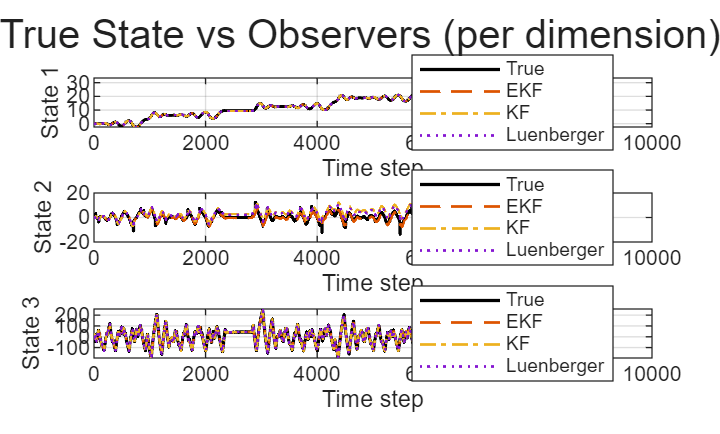

% plot each one
% Create 3 subplots, one for each state dimension, comparing true vs observers
nDims = size(xtrue,2);
figure;
for i = 1:3
    subplot(3,1,i);
    plot(t, xtrue(:,i), 'k-', 'LineWidth', 1.25); hold on;
    plot(t, xhat_EKF(:,i), '--', 'LineWidth', 1);
    plot(t, xhat_KF(:,i), '-.', 'LineWidth', 1);
    plot(t, xhat_luenberger(:,i), ':', 'LineWidth', 1);
    hold off;
    grid on;
    xlabel('Time step [0.01 s]');
    ylabel(sprintf('State %d', i));
    legend('True','EKF','KF','Luenberger','Location','best');
end
sgtitle('True State vs Observers (per dimension)');

## Part 3: MASSIVE COCK

% NOW WE ARE CORRECTING THE REFERENCE
load('MASSIVE_swinging_dick.mat');

xhat_KF = xhat_KF.data;
xtrue = xtrue.data;
xhat = xhat.data;
% Time vector (assume columns correspond to time steps)
T = size(xtrue,1);
t = 1:T;

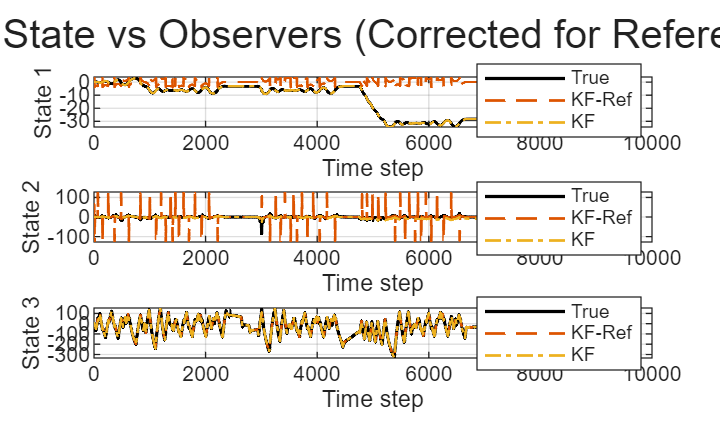

% plot each one
% Create 3 subplots, one for each state dimension, comparing true vs observers
nDims = size(xtrue,2);
figure;
for i = 1:3
    subplot(3,1,i);
    plot(t, xtrue(:,i), 'k-', 'LineWidth', 1.25); hold on;
    plot(t, xhat(:,i), '--', 'LineWidth', 1);
    plot(t, xhat_KF(:,i), '-.', 'LineWidth', 1);
    hold off;
    grid on;
    xlabel('Time step [0.01 s]');
    ylabel(sprintf('State %d', i));
    legend('True','KF-Ref','KF','Location','best');
end
sgtitle('True State vs Observers (Corrected for Reference)');

## Part 4: SPIKES REMOVED

load('SPIKES_ERADICATED.mat');

xhat_KF = xhat_KF.data;
xtrue = xtrue.data;
xhat = xhat.data;
% Time vector (assume columns correspond to time steps)
T = size(xtrue,1);
t = 1:T;

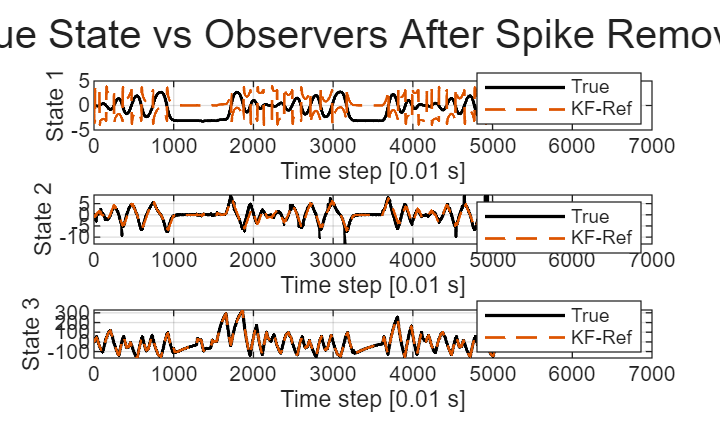

% plot each one
% Create 3 subplots, one for each state dimension, comparing true vs observers
nDims = size(xtrue,2);
figure;
for i = 1:3
    subplot(3,1,i);
    plot(t, xtrue(:,i), 'k-', 'LineWidth', 1.25); hold on;
    plot(t, xhat(:,i), '--', 'LineWidth', 1);
    %plot(t, xhat_KF(:,i), '-.', 'LineWidth', 1);
    hold off;
    grid on;
    xlabel('Time step [0.01 s]');
    ylabel(sprintf('State %d', i));
    legend('True','KF-Ref','Location','best');
end
sgtitle('True State vs Observers After Spike Removal');

% try LP filter

% talk about how robust KF is 